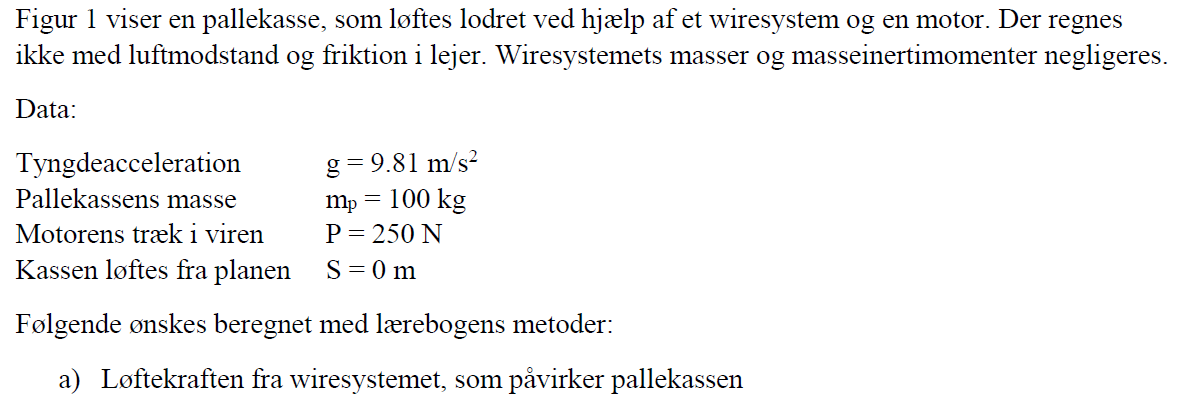

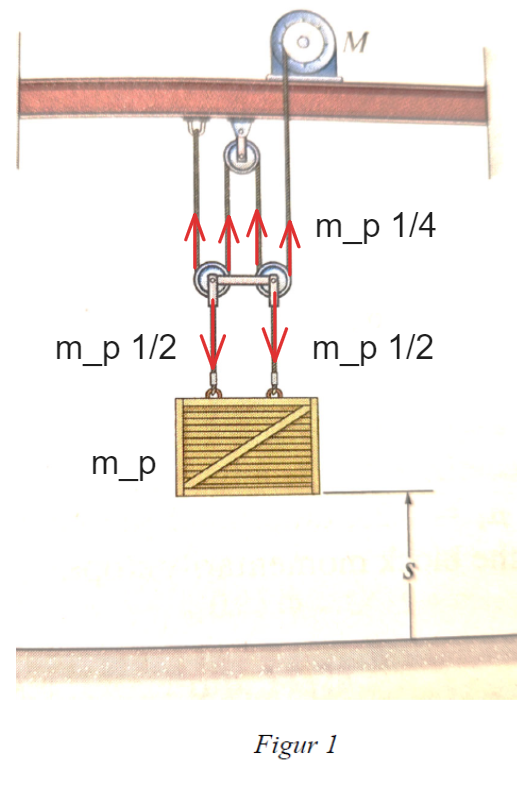

U er det totale arbejde på systemet

V er den potentielle energi

T er kinetisk energi

a)

clear all
format short g

g  = 9.81;  %m/s
m_p = 100; %kg
P = 250; %N
S_0 = 0;

F_wire = 4 * P %3 * m_p/4 * g

F_wire =         1000


Wiresytemet består af 4 lodrette løft der har vægten fordelt ligelidt såldes er den total løftekraft af systemet $1000\ N$

b)

Kassen skal løftes 3 m af 4 * 250N krafter således

S_1 = 3; %m
S_wire = S_1%4 * S_1;

S_wire =      3



U = S_wire *  F_wire

U =         3000


Arbejdet fra wire systemet er således 3000 J

c)

Den potentielle energi er nu


V_pot = S_1 * m_p * g

V_pot =         2943


d)


$$U = V_{pot} + T$$
 

e)

syms v
T = 1/2 * m_p * v^2

$$T = 50\,v^{2}$$


eq = U == V_pot + T

$$eq = 3000=50\,v^{2}+2943$$


v_sol = solve(eq, v);

vpa(v_sol(2), 3)

$$ans = 1.07$$

clear all

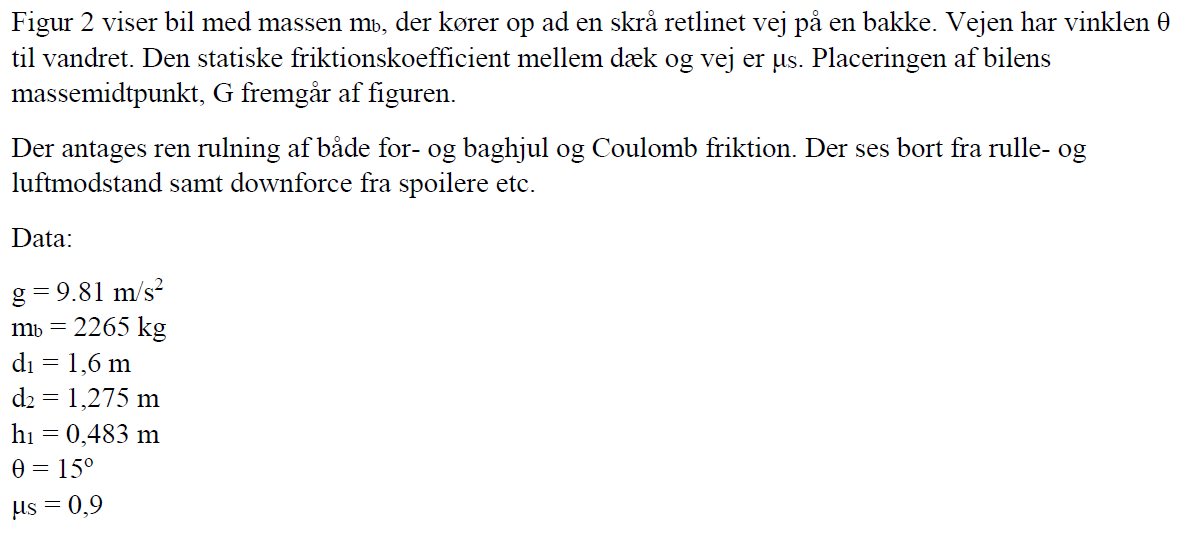

a)

FBD - diagram

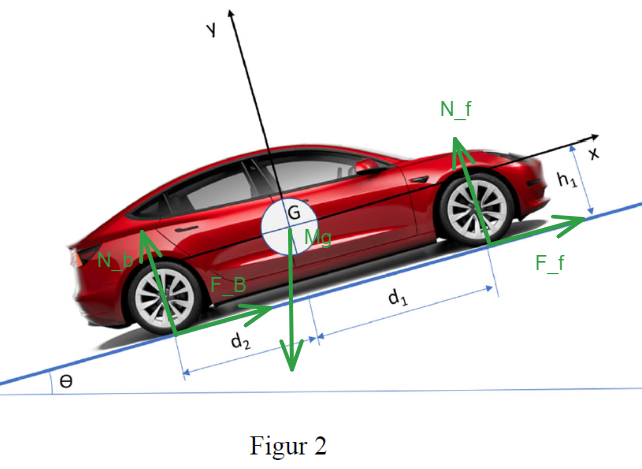

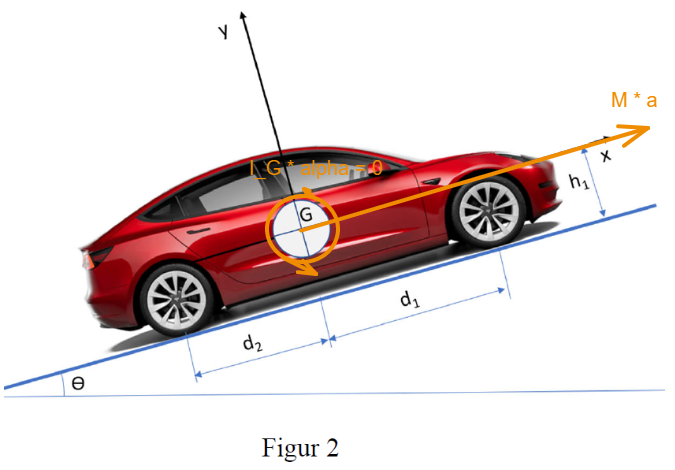

KD - digram

b)

ligning 1 for x komposanten


$$F_F + F_B - M*g * sin(\theta) = M * a_x \\$$
 

Ligning 2 for y - komposanten


$$N_F + N_B - M * g * cos(\theta) = M * a_y = 0$$


Ligning 3 moment ligning


$$-N_B * d_2 + N_F * d_1 +  (F_F + F_B) * h_1 =  I_G * \alpha = 0$$


c)


$$F_F = \mu * N_F =\mu_s * M/2 * g * cos(\theta)$$
 


$$F_B = \mu * N_B  =  \mu_s * M/2 * g * cos(\theta)$$
 

d)

g = 9.81; %m/s^2
m_b = 2265; %kg
d_1 = 1.6; %m
d_2 = 1.275; %m
h_1 = 0.483; %m
theta = 15; % grader
mu_s = 0.9;

N_F = m_b / 2 * g * cosd(theta)

N_F =         10731


N_B = m_b / 2 * g * cosd(theta)

N_B =         10731



F_F = mu_s * N_F

F_F =        9658.1


F_B = mu_s * N_B

F_B =        9658.1



syms a_x

eq_x = F_F + F_B - m_b * g * sind(theta) == m_b * a_x

$$eq\_x = \frac{7457664011421659}{549755813888}=2265\,a_{x}$$


sol_a_x1 = solve(eq_x , a_x);
vpa(sol_a_x1, 4)

$$ans = 5.989$$

eller man kan løse de 3 ligninge med 3 ubekendte $N_F$ $N_B$ og $a_x$


syms N_F N_B a_x

F_F = mu_s * N_F

$$F\_F = \frac{9\,N_{F}}{10}$$


F_B = mu_s * N_B

$$F\_B = \frac{9\,N_{B}}{10}$$


eq_x = F_F + F_B - m_b * g * sind(theta) == m_b * a_x

$$eq\_x = \frac{9\,N_{B}}{10}+\frac{9\,N_{F}}{10}-\frac{3161573445288763}{549755813888}=2265\,a_{x}$$


eq_y = N_F + N_B - m_b * g * cosd(theta) == 0

$$eq\_y = N_{B}+N_{F}-\frac{5899576364839123}{274877906944}=0$$


-N_B * d_2 + N_F * d_1 + (F_F + F_B) * h_1 == 0

$$ans = \frac{20347\,N_{F}}{10000}-\frac{8403\,N_{B}}{10000}=0$$




[sol_N_F, sol_N_B, sol_a_x] = solve([eq_x, eq_y, N_B], [N_F, N_B, a_x]);

vpa(sol_a_x,4)

$$ans = 5.989$$

e)

theta = 0; % grader

syms N_F N_B a_x F_B

eq_F_B = F_B == mu_s * N_B

$$eq\_F\_B = F_{B}=\frac{9\,N_{B}}{10}$$


F_F = 0; %mu_s * N_B

eq_x = F_F + F_B - m_b * g * sind(theta) == m_b * a_x

$$eq\_x = F_{B}=2265\,a_{x}$$


eq_y = N_F + N_B - m_b * g * cosd(theta) == 0

$$eq\_y = N_{B}+N_{F}-\frac{3053845442514125}{137438953472}=0$$


eq_N_B = -N_B * d_2 + N_F * d_1 + (F_F + F_B) * h_1 == 0

$$eq\_N\_B = \frac{483\,F_{B}}{1000}-\frac{51\,N_{B}}{40}+\frac{8\,N_{F}}{5}=0$$




[sol_N_F, sol_N_B, sol_a_x, sol_F_B] = solve([eq_x, eq_y, eq_N_B, eq_F_B], [N_F, N_B, a_x, F_B]);

vpa(sol_N_F,4)

$$ans = 7651.0$$

vpa(sol_N_B,4)

$$ans = 14570.0$$

vpa(sol_a_x,4)

$$ans = 5.789$$

vpa(sol_F_B,4)

$$ans = 13110.0$$




% N_F = m_b / 2 * g * cosd(theta)
% N_B = m_b / 2 * g * cosd(theta)
% 
% F_F = mu_s * N_F
% F_B = mu_s * N_B
% 
% syms a_x
% 
% eq_x =  F_B - m_b * g * sind(theta) == m_b * a_x
% 
% sol_a_x1 = solve(eq_x , a_x);
% vpa(sol_a_x1, 4)


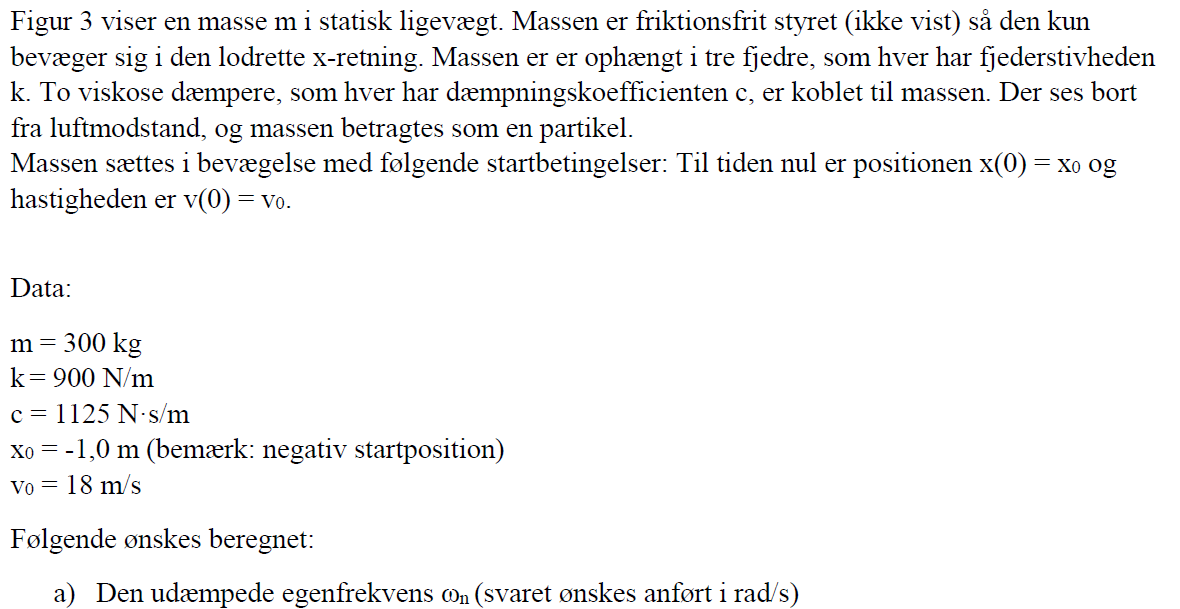

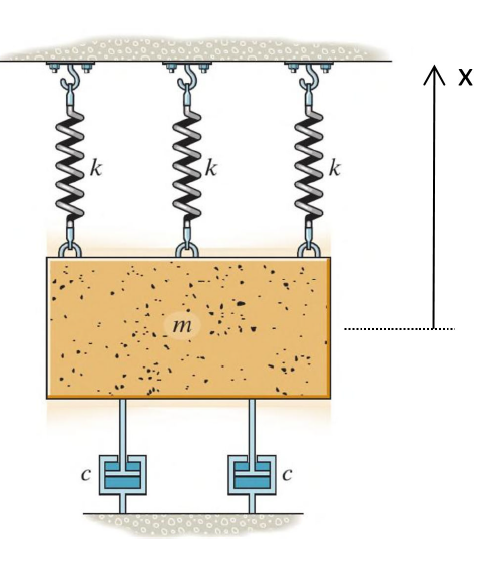

De 3 fjedre sidder i paralel

De 2 dæmperne sidder i paralel 

clear all

k = 3 *900 %N/m

k =         2700


c = 2*1125 % N* s/m

c =         2250


m = 300 %kg

m =    300


x_0 = -1 % m

x_0 =     -1



% u = symunit;


wn = sqrt(k/m)

wn =      3


Svar til opgave a

Egenfrekvensen bliver


$$\omega_n = \sqrt{\frac{k}{m}} = 3 \frac{rad}{s}$$


b)


zeta = c/(2*m*wn)

zeta =          1.25


Svar til opgave b

Udregning af dæmpningsforhold giver


$$\zeta = \frac{c}{2m\omega_n} = 1.25$$


Hvilken betyder der er med en overdæmpet svingning at gøre

c)

t0 = 0;
t1 = 2;

x0 = -1;    % m
v0 = 18;    % m/s

syms A1 A2 t x1 

% Ligning 8/10 fra bogen benyttes og sættes lig startpositionen
x_plac_t0 = A1*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2*exp((-zeta-sqrt(zeta^2-1))*wn*t) == x0;
x_plac_t1 = A1*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2*exp((-zeta-sqrt(zeta^2-1))*wn*t) == x1;

% Hastigheden kommer fra at differentiere placeringsfunktionen, og sætte
% den lig starthastigheden
x_vel = diff(lhs(x_plac_t0), t) == v0

$$x\_vel = -\frac{3\,A_{1}\,{\mathrm{e}}^{-\frac{3\,t}{2}}}{2}-6\,A_{2}\,{\mathrm{e}}^{-6\,t}=18$$


% Ligningerne og de ukendte løses
eqs = [x_plac_t0, x_vel];
vars = [A1, A2];

sols = solve(eqs, vars)

sols = struct with fields:
    A1: (8*exp((3*t)/2))/3
    A2: -(11*exp(6*t))/3



% Konstanterne A1 og A2 udregnes, og sættes ind i diff ligningerne til
% tiden t0

A1_ny = vpa(subs(sols.A1, t, t0),4)

$$A1\_ny = 2.667$$

A2_ny = vpa(subs(sols.A2, t, t0),4)

$$A2\_ny = -3.667$$


% Funktionen præsenteres
funktion = vpa(subs(lhs(x_plac_t1), [A1, A2], [A1_ny, A2_ny]),4)

$$funktion = 2.667\,{\mathrm{e}}^{-1.5\,t}-3.667\,{\mathrm{e}}^{-6.0\,t}$$

Svar til opgave c)

Da det er fundet at der er med en overdæmpet funktion at gøre, bruges formel 8/10 i bogen (her er den kaldt $x_{plac, t_0}$), og der løses for konstanterne A1 og A2.

De tidligere udregnede værdier for 


$$\zeta = 1.25$$



$$\omega_n = 3$$


Er brugt i formlen.

Når der er løst for A1 og A2, som hhv er


$$A_1 = 2,667$$



$$A_2 = -3,667$$


Indsættes de i startformlen 8/10, og følgende funktion fås


$$x(t) = 2,667e^{1,5\cdot t} - 3,667e^{-6\cdot t}$$


d)

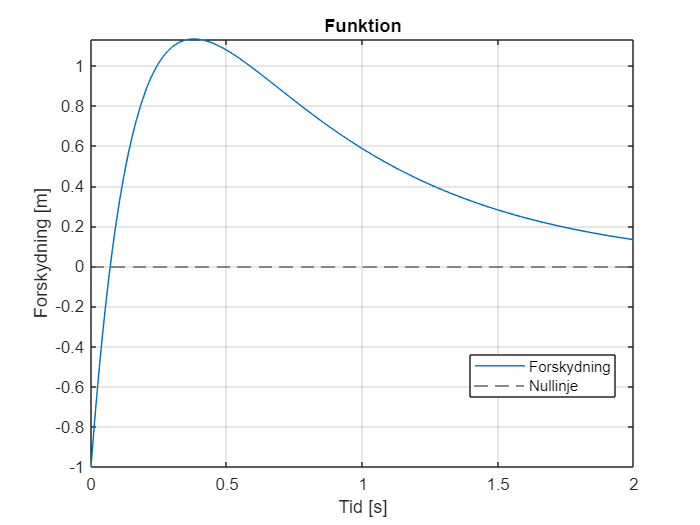

syms func(t)

func(t) = A1_ny*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2_ny*exp((-zeta-sqrt(zeta^2-1))*wn*t);

fplot(func(t), [t0,t1], "DisplayName", "Forskydning"), xlabel("Tid [s]"), ylabel("Forskydning [m]"), grid()
yline(t0, '--', "DisplayName", "Nullinje")

title("Funktion");

legend("Location","best")

e)

tlin = linspace(0, 2, 1000);

xmax = A1_ny*exp((-zeta + sqrt(zeta^2 - 1))*wn*tlin) + A2_ny*exp((-zeta-sqrt(zeta^2-1))*wn*tlin);

[xmax, I] = max(xmax);


I =    190


maks = vpa(xmax,5)

$$maks = 1.133$$

tid = vpa(tlin(I),4)

$$tid = 0.3784$$